## **Assignment 1: Date, time, and time transformations**

**Task1:**

Function used is R_i = rot3d(angle,axis)

Two imput arguments are required to for the function rot3d. For more information use 'doc rot3d'.

for axis = 1:3

    R_2pi = rot3d(rad2deg(2*pi),axis);
    R_0 = rot3d(rad2deg(0),axis);
    R_pi = rot3d(rad2deg(pi),axis);
    Eye_3 = eye(3);
    
    if (sum(sum(R_2pi == R_0))==9 && ...
    sum(sum(R_2pi == R_pi*R_pi))==9 && ...
    sum(sum(R_2pi == Eye_3))==9 && ...
    sum(sum(R_0 == R_pi*R_pi))==9 && ...
    sum(sum(R_0 == Eye_3))==9 && ...
    sum(sum(R_pi*R_pi == Eye_3))==9)
   
        disp(append("rot3d seems to be correct for axis: ",num2str(axis)))
    else
        error("rot3d works NOT like intended.")
    end
end

rot3d seems to be correct for axis: 1
rot3d seems to be correct for axis: 2
rot3d seems to be correct for axis: 3


Check function rot3d with a test vector:

x = [1,0,0]'

x =      1
     0
     0



e1 = rot3d(90,2)*x

e1 =      0
     0
     1


e2 = rot3d(90,3)*x

e2 =      0
    -1
     0


e3 = rot3d(90,1)*x

e3 =      1
     0
     0


From perspective at the origin the matrices are roatating counterclockwise when using positive angles.

**Task2:**

Function used is [R_ref] = ref3d(axis)

Checking the results with the Identity matrix:

for axis = 1:3
    if (sum(sum(ref3d(axis)*ref3d(axis) == eye(3)))==9)
        disp(append("ref3d seems to be correct for axis: ",num2str(axis)))
    else
        error("ref3d works NOT like intended.")
    end
end

ref3d seems to be correct for axis: 1
ref3d seems to be correct for axis: 2
ref3d seems to be correct for axis: 3


Checking the results with mutltiplication of reflection matrixes:

if (sum(sum(ref3d(1)*ref3d(2)*ref3d(3) == -eye(3)))==9)
        disp("ref3d works like intended.")
else
        error("ref3d works NOT like intended.")
end

ref3d works like intended.


=> Because M1*M2 == M2*M1 this works for all combinations

**Task3:**

Function used is [E,it] = kepler_ecc_ano(M,e)

For the kepler_ecc_ano function an extra paramtermeter could be introduced to define the starting value.

[E,iterations] = kepler_ecc_ano(10,0.5) %Some test values

E =           9.81144735368769


iterations =     18


The Grid

M_an=0:0.01:2*pi;
ecc=0:0.001:(1-0.001);

keplergrid_E =  zeros(length(M_an),length(ecc));
keplergrid_it =  zeros(length(M_an),length(ecc));
keplergrid_diff =  zeros(length(M_an),length(ecc));

for i_M_an = 1:length(M_an)
    for i_ecc = 1:length(ecc)

        [keplergrid_E(i_M_an,i_ecc), keplergrid_it(i_M_an,i_ecc)] = ...
            kepler_ecc_ano(M_an(i_M_an),ecc(i_ecc));
        keplergrid_diff(i_M_an,i_ecc) = keplergrid_E(i_M_an,i_ecc)-M_an(i_M_an);
    end
end

Plot iterations

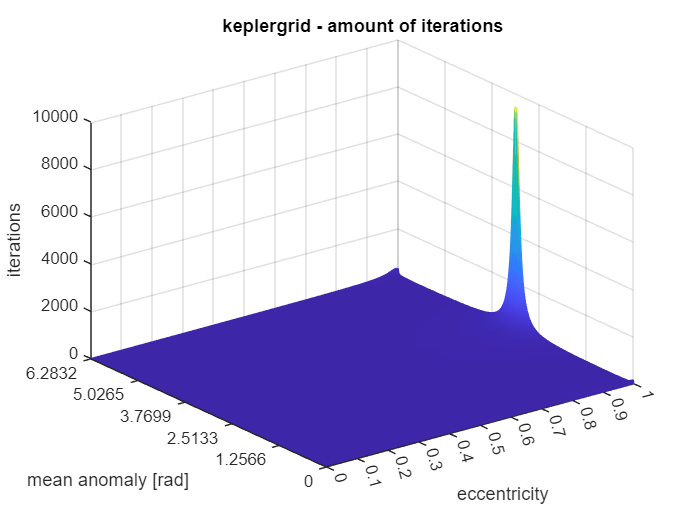

figure;
mesh(keplergrid_it)
title('keplergrid - amount of iterations');
xlabel('eccentricity');
ylabel('mean anomaly [rad]');
zlabel('iterations');
xticks([0,100,200,300,400,500,600,700,800,900,1000])
xticklabels({'0','0.1','0.2','0.3','0.4','0.5','0.6','0.7','0.8','0.9','1'})
yticks([0,pi*40,pi*80,pi*120,pi*160,pi*200])
yticklabels({'0',num2str((pi/100)*40),num2str((pi/100)*80), ...
    num2str((pi/100)*120),num2str((pi/100)*160),num2str((pi/100)*200)})

Plot difference

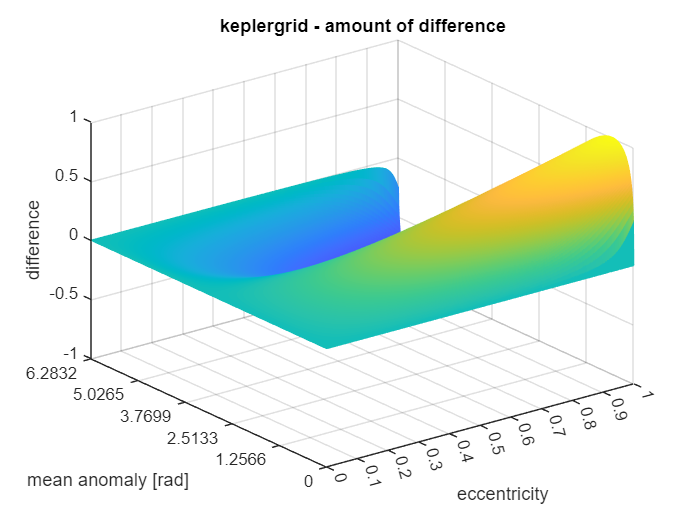

figure;
mesh(keplergrid_diff)
title('keplergrid - amount of difference');
xlabel('eccentricity');
ylabel('mean anomaly [rad]');
zlabel('difference');
xticks([0,100,200,300,400,500,600,700,800,900,1000])
xticklabels({'0','0.1','0.2','0.3','0.4','0.5','0.6','0.7','0.8','0.9','1'})
yticks([0,pi*40,pi*80,pi*120,pi*160,pi*200])
yticklabels({'0',num2str((pi/100)*40),num2str((pi/100)*80), ...
    num2str((pi/100)*120),num2str((pi/100)*160),num2str((pi/100)*200)})

**Task4:**

For the question what the difference is between the two functions:

There is no a really big difference. By converting to degrees,minutes

and seconds, the seperated values get multiplyed bei 60 or 3600 and by 

converting to decimal degrees they are getting divided by 60 or 3600.

Just a lilte note to the two functions:

The task was to convert a vector of angles with unit decimal degree

into vectors of degree, minute and decimal second.

We instead convertet the decimal degree vector into a matrix of

degree, minute and decimal seconds. The reason behind this change is

that is way more clear where every coordinate starts and ends. 

Becuase of this change is also way more easy to use in further functions.

TestDecimalDegrees = [-31.2342,12.425,93.2334,-178.23]

TestDecimalDegrees =   -31.2342   12.4250   93.2334 -178.2300


De_Mi_Se_Matrix = DecDeg_To_De_Mi_Se(TestDecimalDegrees)

De_Mi_Se_Matrix =   -31.0000   14.0000    3.1200
   12.0000   25.0000   30.0000
   93.0000   14.0000    0.2400
 -178.0000   13.0000   48.0000


DecDegVector = De_Mi_Se_To_DecDeg(De_Mi_Se_Matrix)

DecDegVector =   -31.2342   12.4250   93.2334 -178.2300



if (sum(TestDecimalDegrees == DecDegVector)==length(TestDecimalDegrees))
        disp("The Decimal Degrees got transferd between the two functions " + ...
            "without correctly.")
else
        error("DecDeg_To_De_Mi_Se and De_Mi_Se_To_DecDeg arent inverse " + ...
            "to each other.")
end

The Decimal Degrees got transferd between the two functions without correctly.


**Task5:**

year = 2021;
month = 11;
day = 22; 
hour = 01; %CET
minute = 0;
second = 0;

Change time zone

[year,month,day,hour] = CET_hour_To_UTC_hour(year,month,day,hour);

Corrected Time

[year,month,day,hour,minute,second] = Get_UT1_sec(year,month,day,hour,minute,second)

year =         2021


month =     11


day =     21


hour =     23


minute =     59


second =                 59.8926913


[jd_UT1,~] = gre2jd(year,month,day,hour,minute,second);

Calculate Earth roation angle / Calculate T_UT1

T_UT1 = jd_UT1 - 2451545.0;

ERA = 2 * pi * ...
    (0.7790572732640 + 1.00273781191135448 * T_UT1);

Ra_ERA = Get_Radius_From_Cycles_of_Radius(ERA);

Convert radiant to degree

Randiant_to_Degree_value = 360/(2*pi);

deg = Randiant_to_Degree_value*Ra_ERA;

Calculate the Decimal hours, minutes and seconds

De_Mi_Se_ERA = DecDeg_To_De_Mi_Se(deg);

De_Mi_Se_ERA(3) = round(De_Mi_Se_(3));

Earth roation angle:

De_Mi_Se_ERA

De_Mi_Se_ERA =     60    55    24


Greenwich Apparent Sidereal Time

t = (jd_UT1 -2451545.0)/36525;

GMST = (F(jd_UT1)*86400 + 24110.54841 -86400/2 + ...
8640184.812866 * t + 0.093104 * t * t -...
6.2e-6 * t * t * t)/3600; % hour

equinox = get_equinox(year,month,day,jd_UT1)

equinox =      -1.87330546029266e-06


GAST = GMST + equinox;

GAST = Get_Hours_From_HourCycles(GAST);

DecDeg_To_De_Mi_Se(GAST)

ans =     4.0000    4.0000   48.8826


**Task6:**

VLBI_Group_Delay_TT = 0.02 %sconds in TT

VLBI_Group_Delay_TT =                       0.02


VLBI_Group_Delay_TCG = TTdiv_To_TCGdiv(VLBI_Group_Delay_TT)

VLBI_Group_Delay_TCG =         0.0200000000139386


VLBI_Group_Delay_TCB = TCGdiv_To_TCBdiv(VLBI_Group_Delay_TCG)

VLBI_Group_Delay_TCB =         0.0200001975856417


Difference in meter

c = 299792458; %m/s

VLBI_Group_Delay_In_Meter = ((c * VLBI_Group_Delay_TCB) / c) - ...
    ((c * VLBI_Group_Delay_TT) / c);

disp(append("The difference is: ", ...
    num2str(VLBI_Group_Delay_In_Meter * 10^6), " micro meter"))

The difference is: 0.19759 micro meter


Ratio between gravitational relativistic term and special relativistic term

% Values from the calculations as in the function TCGdiv_To_TCBdiv
gravitantional_potential = 887384185629.236;
Special_relativistic_term = 450000000;

GS_ratio = gravitantional_potential / Special_relativistic_term;
disp(append("gravitantional_potential is ", ...
    num2str(GS_ratio), " times as large as the Special_relativistic_term"))

gravitantional_potential is 1971.9649 times as large as the Special_relativistic_term


We can't see that the gravitational relativistic term is about twice as large as the special relativistic term. 